clear;
clc;

Завантажуєм файл

load mri.mat;
D=squeeze(D);

Різні способи збільшення яскравості

% for image_num=1:siz(3)
%     img = D(:,:,image_num);
%     img = imresize(img, 2);
%     
%     figure;
%     subplot(1,4,1);
%     montage(img);
%     title("Original");
%     
%     h = histeq(img);
%     subplot(1,4,2);
%     montage(h);
%     title("Histeq filter");
%     
%     imad = imadjust(img);
%     subplot(1,4,3);
%     montage(imad);
%     title("Imadjust filter");
%     
%     adap = adapthisteq(img);
%     subplot(1, 4, 4);
%     montage(adap);
%     title("Adapthisteq filter");
% end

Вибране зображення 16

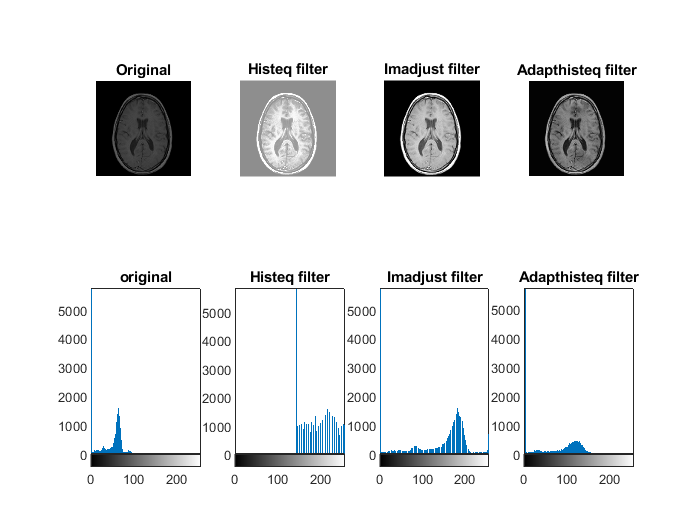

img = D(:,:,16);
img = imresize(img, 2);

figure;
subplot(2,4,1);
montage(img);
title("Original");

%збільшення або зменшення його контрастності, є вирівнювання його
%гістограми – розподілу яскравості пікселів зображення.
h = histeq(img);
subplot(2,4,2);
montage(h);
title("Histeq filter");

%я гама-корекція
imad = imadjust(img);
subplot(2,4,3);
montage(imad);
title("Imadjust filter");

% автоматичне вирівнюванням гістограми
adap = adapthisteq(img);
subplot(2, 4, 4);
montage(adap);
title("Adapthisteq filter");

subplot(2, 4, 5);
imhist(img);
title("original")

subplot(2, 4, 6);
imhist(h);
title("Histeq filter");

subplot(2, 4, 7);
imhist(imad);
title("Imadjust filter");


subplot(2, 4, 8);
imhist(adap);
title("Adapthisteq filter");

Вибрав зображення з фільтром Adapthisteq

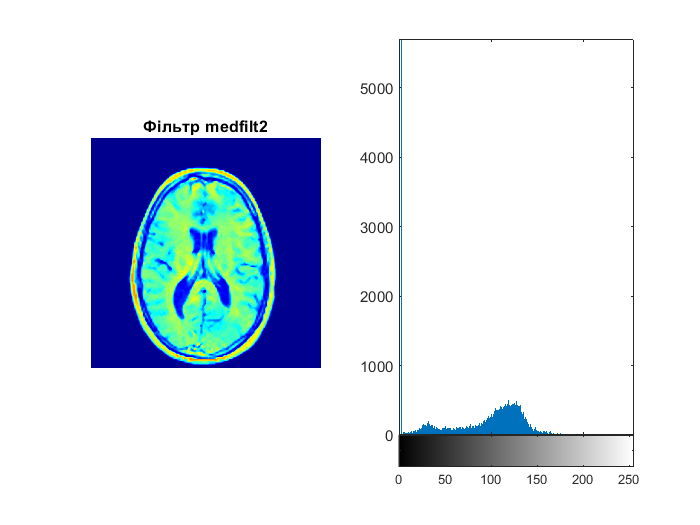

%медіанна фільтрація
med = medfilt2(adap);
figure;
subplot(1, 2, 1);
montage(med);
title('Фільтр medfilt2')
colormap('jet');

subplot(1, 2, 2);
imhist(med);

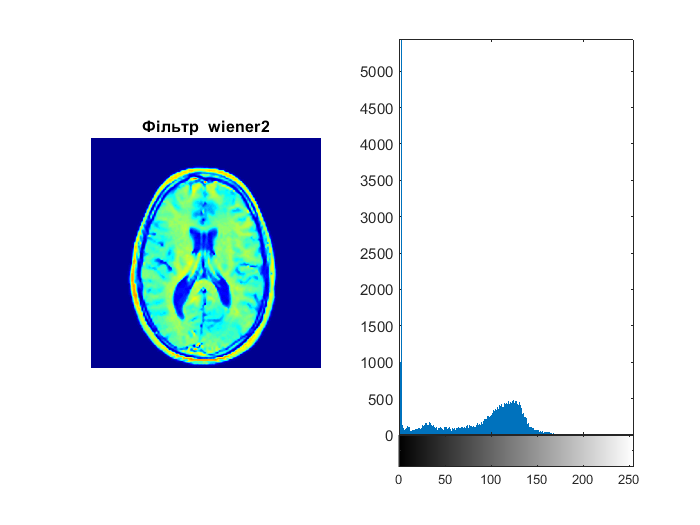


%адаптивна фільтрація зображення методом Вінера
win = wiener2(adap);
figure;
subplot(1, 2, 1);
montage(win);
title("Фільтр  wiener2");
colormap('jet');

subplot(1, 2, 2);
imhist(win);

Гаусівський Шум

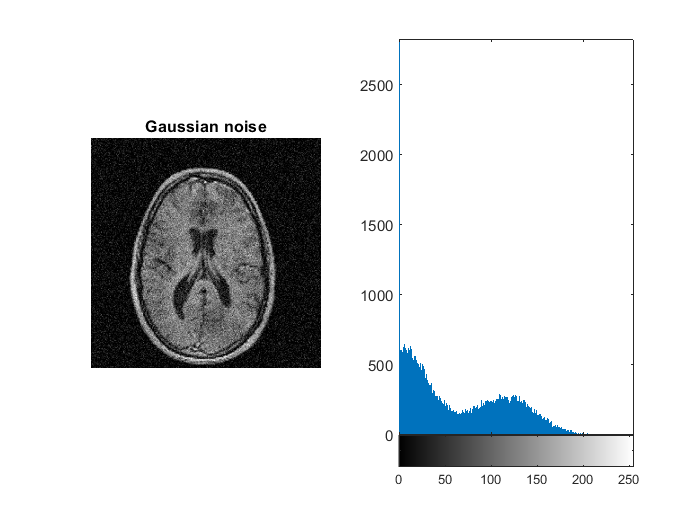

gau = imnoise(adap, "gaussian");

figure;
subplot(1, 2, 1);
montage(gau);
title("Gaussian noise");

subplot(1, 2, 2);
imhist(gau);

Імпульсний шум

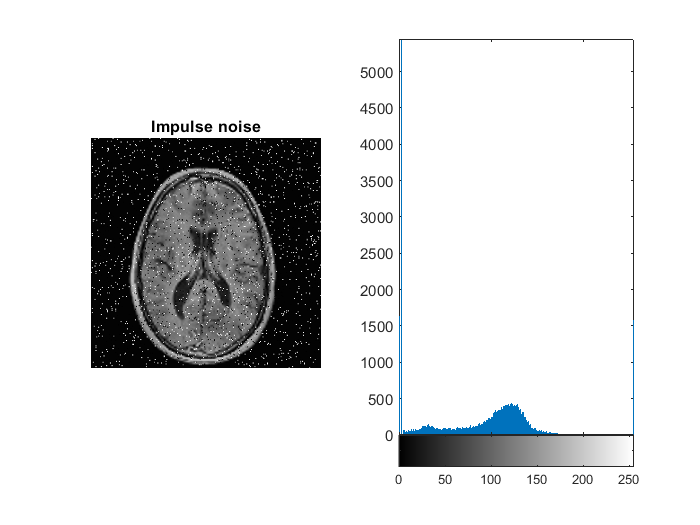

imp = imnoise(adap, 'salt & pepper');

figure;
subplot(1, 2, 1);
montage(imp);
title("Impulse noise");

subplot(1, 2, 2);
imhist(imp);

Пуасонівський шум

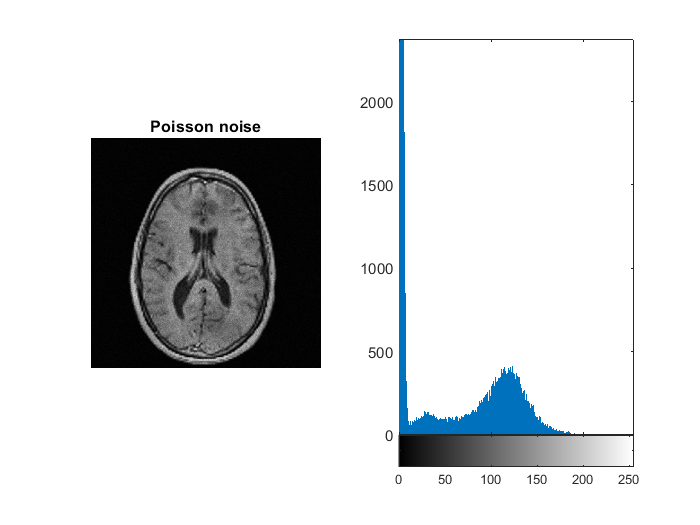

poi = imnoise(adap, 'poisson');

figure;
subplot(1, 2, 1);
montage(poi);
title("Poisson noise")

subplot(1, 2, 2);
imhist(poi);

Мультиплікативний шум

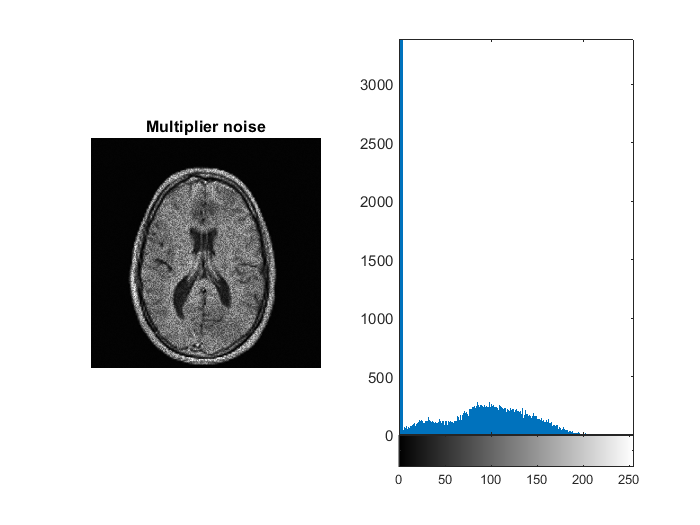

spec = imnoise(adap, 'speckle');

figure;
subplot(1, 2, 1);
montage(spec);
title("Multiplier noise");

subplot(1, 2, 2);
imhist(spec);

Медіанний фільтр для зашумленого зображення

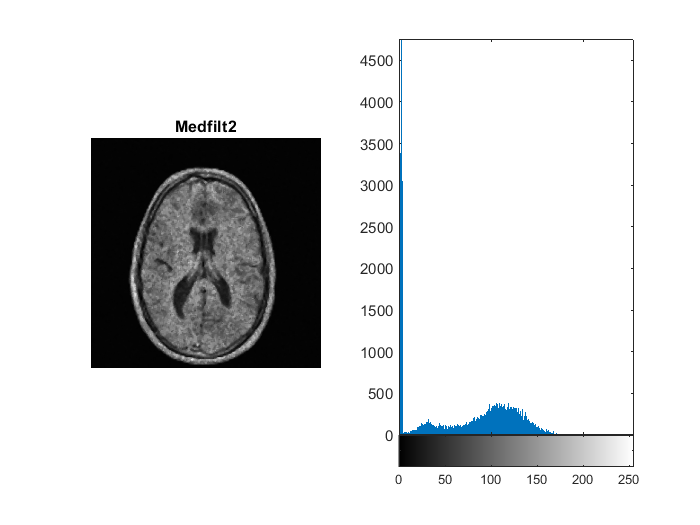

filter_med = medfilt2(spec);

figure;
subplot(1, 2, 1);
montage(filter_med);
title("Medfilt2")

subplot(1, 2, 2);
imhist(filter_med);

Максимізуючий фільтр для зашумленого зображення

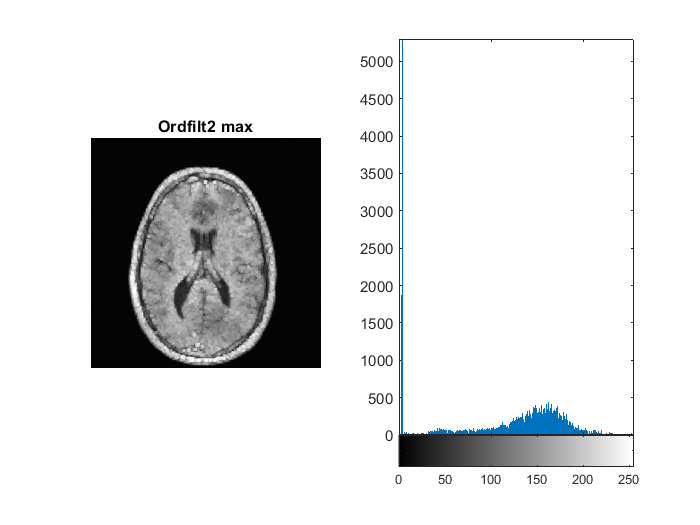

filter_ord_max = ordfilt2(spec, 9, ones(3, 3));

figure;
subplot(1, 2, 1);
montage(filter_ord_max);
title("Ordfilt2 max");

subplot(1, 2, 2);
imhist(filter_ord_max);

Мінімізуючий фільтр для зашумленого зображення

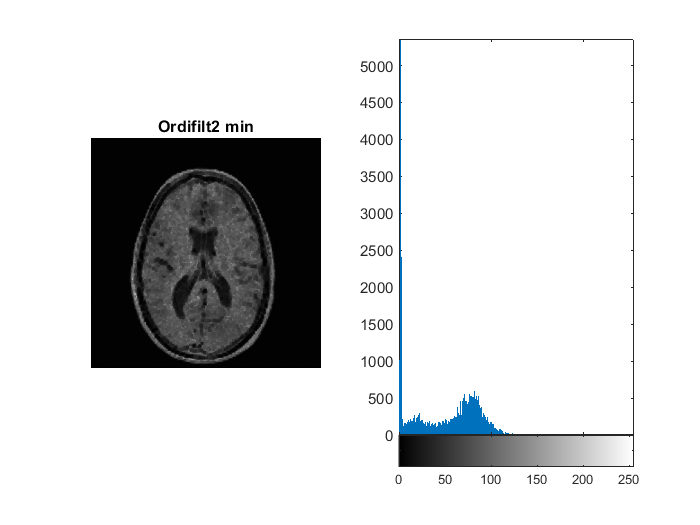

filter_ord_min = ordfilt2(spec, 1, ones(3, 3));

figure;
subplot(1, 2, 1);
montage(filter_ord_min);
title("Ordifilt2 min");

subplot(1, 2, 2);
imhist(filter_ord_min);